# 主程序：机器人多点轨迹规划

clear; clc; close all;

## 创建机器人模型

% 定义连杆长度
d4_val = 0.187 + 0.063; 

% 建立 Standard DH 模型
L(1) = Link('revolute', 'd', 0.12202, 'a', 0.1, 'alpha', -pi/2, 'standard');
L(2) = Link('revolute', 'd', 0, 'a', 0.25, 'alpha', 0, 'standard', 'offset', -pi/2);
L(3) = Link('revolute', 'd', 0, 'a', 0, 'alpha', pi/2, 'standard', 'offset', pi);
L(4) = Link('revolute', 'd', d4_val, 'a', 0, 'alpha', -pi/2, 'standard');
L(5) = Link('revolute', 'd', 0, 'a', 0, 'alpha', pi/2, 'standard');
L(6) = Link('revolute', 'd', 0.0595, 'a', 0, 'alpha', 0, 'standard');
EpsonC3 = SerialLink(L, 'name', 'Epson C3 A601', 'base', transl(0,0,0.198));
file_path = "D:\School\大三上\机器人仿真技术基础\大作业\大作业\EpsonC3A601_SW"';

## 设置工作空间和关节限制

workspace = [-0.5 0.5 -0.5 0.5 0 0.8];
qlim = [
    -170/180*pi, 170/180*pi;      -160/180*pi, 65/180*pi;    -51/180*pi, 225/180*pi;
    -200/180*pi, 200/180*pi;      -135/180*pi, 135/180*pi;   -360/180*pi, 360/180*pi;
];

## 定义多点路径和移动类型

路径点 [x, y, z]

path_points = {
    [0.4095, 0.0000, 0.570];    % 点1(初始状态，关节角均为零)
    [0.35, 0, 0.5];    [0.1, 0.4, 0.20];   
    % 点2 (物体1)            % 点3 (放置点1)
    [0.35, -0.10, 0.5];    [0, 0.4, 0.20];  
    % 点4 (物体2)            % 点5 (放置点2)
    [0.35, -0.20, 0.5];    [-0.1, 0.4, 0.20];  
    % 点6 (物体3)            % 点7 (放置点3)
    [0.35, 0, 0.40];    [0.1, 0.5, 0.20];     
    % 点8 (物体4)            % 点9 (放置点4)
    [0.35, -0.10, 0.40];    [0, 0.50, 0.20];    
    % 点10 (物体5)           % 点11 (放置点5)
    [0.35, -0.20, 0.40];    [-0.1, 0.50, 0.20];     
    % 点12 (物体6)           % 点13 (放置点6)
};

% T_start = transl(0.3, -0.2, 0.500) * rpy2tr(0, pi, 0, 'arm');
% T_goal = transl(0.1, 0.4, 0.2) * rpy2tr(0, pi, 0, 'arm');

% 移动类型: 'PTP', 'LINE', 'ARC'
% path_types = {'PTP', 'LINE', 'PTP', 'LINE', 'PTP', 'LINE',...
%               'LINE', 'PTP', 'LINE', 'LINE', 'PTP', 'LINE'};
%           
path_types = {'PTP', 'PTP', 'PTP', 'PTP', 'PTP', 'PTP',...
              'PTP', 'PTP', 'PTP', 'PTP', 'PTP', 'PTP'};

% 姿态配置（可以为每段路径指定不同的姿态，but未写）
% 如果为1×3，所有点使用相同姿态；如果为N×3，每点使用对应姿态
orientation = [0, pi, 0];  % 固定姿态

% 每段路径时间（秒）
segment_times = [2.0, 3.0, 3.0, 3.0, 3.0, 3.0,...
                 3.0, 3.0, 3.0, 3.0, 3.0, 3.0];

## 执行多点轨迹规划

fprintf('多点轨迹规划开始...\n');

多点轨迹规划开始...


fprintf('总共有 %d 个路径点\n', length(path_points));

总共有 13 个路径点



all_q_traj = [];
all_time = [];
all_ee_positions = [];
current_time = 0;

% 初始化关节角
q_last = [0 0 0 0 0 0];
for i = 1:length(path_types)
    fprintf('\n--- 第 %d 段: 从点%d到点%d, 类型: %s, 时间: %.1f秒 ---\n', ...
            i, i, mod(i, length(path_points))+1, path_types{i}, segment_times(i));
    
    % 获取起点、终点
    start_point = path_points{i};
    end_point = path_points{mod(i, length(path_points))+1};

    % 根据每段的时间计算采样点数
    num_points = segment_times(i)*100+1; % 3秒则采样301个点，2秒则采样201个点(dt = 0.01)

    % 根据路径类型调用相应的轨迹规划函数
    switch path_types{i}
        case 'PTP'
            % PTP轨迹规划
            [q_traj, qd_traj, qdd_traj, time_points, ee_positions] = ptp_trajectory(...
                EpsonC3, start_point, end_point, orientation, ...
                segment_times(i), qlim, num_points, q_last);
            
        case 'LINE'
            % 直线轨迹规划
            [q_traj, qd_traj, qdd_traj, time_points, ee_positions] = line_trajectory(...
                EpsonC3, start_point, end_point, orientation, ...
                segment_times(i), qlim, num_points, q_last);
            
        case 'ARC'
            % 圆弧轨迹规划（需要一个中间点）
            % via_point = zeros(1,3);
            % via_point = choose_third_point(start_point, end_point, 0.05)
            % via_point = [0.4, 0, 0.5]

            [q_traj, qd_traj, qdd_traj, time_points, ee_positions] = arc_trajectory(...
                EpsonC3, start_point, via_point, end_point, ...
                orientation, segment_times(i), qlim, num_points, q_last);
    end
    q_last = q_traj(end,:);
    % qd_last = qd_traj(end,:);

    % 调整时间（加上之前的时间）
    time_points = time_points + current_time;
    current_time = time_points(end);
    
    % 拼接轨迹
    if i == 1
        all_q_traj = q_traj;
        all_qd_traj = qd_traj;
        all_qdd_traj = qdd_traj;
        all_time = time_points;
        all_ee_positions = ee_positions;
    else
        % 去掉第一个点（与上一段的最后一个点重复）
        all_q_traj = [all_q_traj; q_traj(2:end, :)];
        all_qd_traj = [all_qd_traj; qd_traj(2:end, :)];
        all_qdd_traj = [all_qdd_traj; qdd_traj(2:end, :)];
        all_time = [all_time; time_points(2:end)];
        all_ee_positions = [all_ee_positions; ee_positions(2:end, :)];
    end
end


--- 第 1 段: 从点1到点2, 类型: PTP, 时间: 2.0秒 ---

--- 第 2 段: 从点2到点3, 类型: PTP, 时间: 3.0秒 ---

--- 第 3 段: 从点3到点4, 类型: PTP, 时间: 3.0秒 ---

--- 第 4 段: 从点4到点5, 类型: PTP, 时间: 3.0秒 ---

--- 第 5 段: 从点5到点6, 类型: PTP, 时间: 3.0秒 ---

--- 第 6 段: 从点6到点7, 类型: PTP, 时间: 3.0秒 ---

--- 第 7 段: 从点7到点8, 类型: PTP, 时间: 3.0秒 ---

--- 第 8 段: 从点8到点9, 类型: PTP, 时间: 3.0秒 ---

--- 第 9 段: 从点9到点10, 类型: PTP, 时间: 3.0秒 ---

--- 第 10 段: 从点10到点11, 类型: PTP, 时间: 3.0秒 ---

--- 第 11 段: 从点11到点12, 类型: PTP, 时间: 3.0秒 ---

--- 第 12 段: 从点12到点13, 类型: PTP, 时间: 3.0秒 ---



fprintf('\n=== 轨迹规划完成 ===\n');


=== 轨迹规划完成 ===


fprintf('总时间: %.2f 秒\n', all_time(end));

总时间: 35.00 秒


fprintf('总轨迹点数: %d\n', size(all_q_traj, 1));

总轨迹点数: 3501


## 计算关节力矩

fprintf('\n计算关节力矩...\n');


计算关节力矩...


num_traj = size(all_q_traj, 1);
all_tau = zeros(num_traj, 6);

% 使用逆动力学计算力矩
for i = 1:num_traj
    % rne() 函数：Recursive Newton-Euler algorithm
    % tau = rne(EpsonC3, q, qd, qdd, [gx gy gz])
    % 考虑重力：[0 0 -9.81]
    all_tau(i,:) = EpsonC3.rne(all_q_traj(i,:), all_qd_traj(i,:), all_qdd_traj(i,:), [0 0 -9.81]);
end

fprintf('力矩计算完成！\n');

力矩计算完成！


## 保存整个过程机器人的关节角，末端位置随时间的变化

创建表格

T = table(all_time, ...
          all_q_traj(:,1), all_q_traj(:,2), all_q_traj(:,3), ...
          all_q_traj(:,4), all_q_traj(:,5), all_q_traj(:,6), ...
          all_qd_traj(:,1), all_qd_traj(:,2), all_qd_traj(:,3), ...
          all_qd_traj(:,4), all_qd_traj(:,5), all_qd_traj(:,6), ...
          all_qdd_traj(:,1), all_qdd_traj(:,2), all_qdd_traj(:,3), ...
          all_qdd_traj(:,4), all_qdd_traj(:,5), all_qdd_traj(:,6), ...
          all_tau(:,1), all_tau(:,2), all_tau(:,3), ...
          all_tau(:,4), all_tau(:,5), all_tau(:,6), ...
          all_ee_positions(:,1), all_ee_positions(:,2), all_ee_positions(:,3), ...
          'VariableNames', {...
               'time', ...
               'q1','q2','q3','q4','q5','q6', ...
               'qd1','qd2','qd3','qd4','qd5','qd6', ...
               'qdd1','qdd2','qdd3','qdd4','qdd5','qdd6', ...
               'tau1','tau2','tau3','tau4','tau5','tau6', ...
               'x','y','z'});

% 保存 CSV
writetable(T, '.\datas\robot_trajectory_table.csv');

## 展示机器人末端三维轨迹

fprintf('\n开始展示机器人末端轨迹...\n');


开始展示机器人末端轨迹...


close all;
% 末端三维轨迹
figure('Position', [100, 100, 800, 600], 'Name', '末端三维轨迹');
hold on;
light('Position', [1, 1, -1], 'color', 'w'); % 打光，不然机械臂有点暗
light('Position', [0, 0, 2], 'color', 'w');
EpsonC3.plot3d(all_q_traj(1, :), 'tilesize', 0.1, 'path', file_path, 'nowrist', 'workspace', workspace, ...
    'scale', 0.5, 'fps', 20);

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


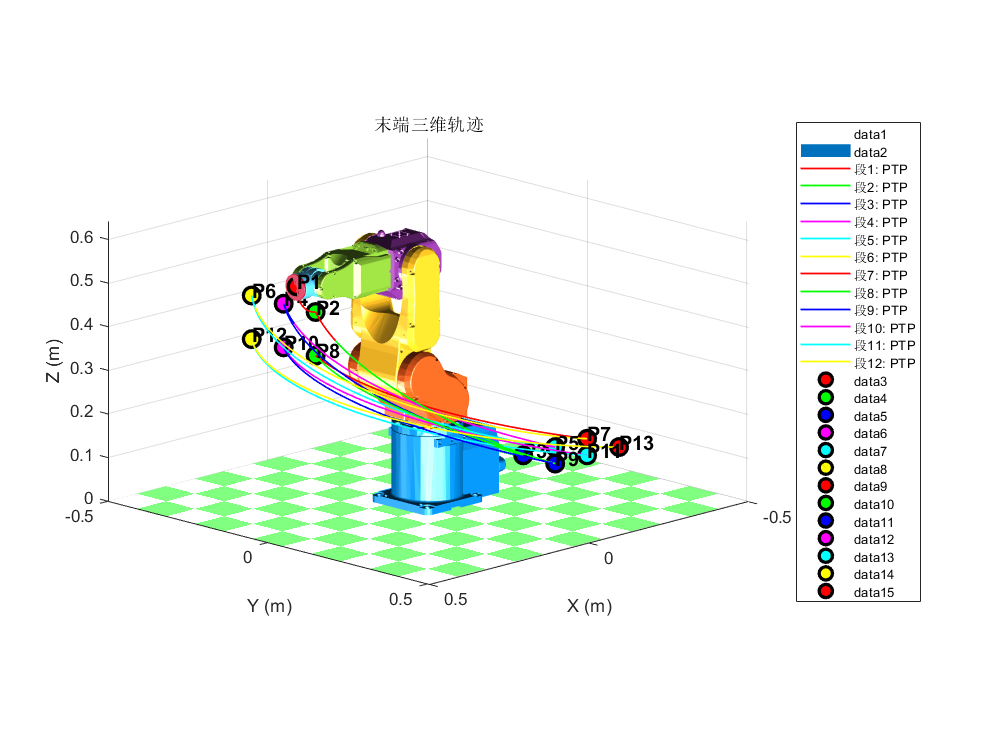

% 用不同颜色绘制每段轨迹
colors = {'r', 'g', 'b', 'm', 'c', 'y'};
current_idx = 1;
for i = 1:length(path_types)
    % 计算当前段的点数（近似）
    segment_points = round(size(all_q_traj, 1) / length(path_types));
    if i == length(path_types)
        end_idx = size(all_ee_positions, 1);
    else
        end_idx = min(current_idx + segment_points - 1, size(all_ee_positions, 1));
    end
    
    % 绘制当前段轨迹
    plot3(all_ee_positions(current_idx:end_idx, 1), ...
          all_ee_positions(current_idx:end_idx, 2), ...
          all_ee_positions(current_idx:end_idx, 3), ...
          'LineWidth', 1, 'Color', colors{mod(i-1,6)+1}, ...
          'DisplayName', sprintf('段%d: %s', i, path_types{i}));
    
    current_idx = end_idx;
end

% 绘制路径点
for i = 1:length(path_points)
    plot3(path_points{i}(1), path_points{i}(2), path_points{i}(3), ...
          'o', 'MarkerSize', 10, 'MarkerFaceColor', colors{mod(i-1,6)+1}, ...
          'MarkerEdgeColor', 'k', 'LineWidth', 2);
    text(path_points{i}(1)+0.02, path_points{i}(2)+0.02, path_points{i}(3)+0.02, ...
         sprintf('P%d', i), 'FontSize', 12, 'FontWeight', 'bold');
end

grid on; xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('末端三维轨迹');
legend('Location', 'eastoutside', 'FontSize', 8);
view(135,15);
axis equal;

## 绘制机器人轨迹装载动画

close all;
figure('Position', [100, 100, 1280, 720], 'Name', '机器人多点轨迹演示', 'Renderer','opengl');

set(gcf,'GraphicsSmoothing','on'); % 抗锯齿
opengl hardware

% 绘制末端轨迹
plot3(all_ee_positions(:,1), all_ee_positions(:,2), all_ee_positions(:,3), ...
       'LineWidth', 0.5, 'DisplayName', '末端轨迹', 'Color',	'#4DBEEE');
title('机器人动画演示');
view(45,30);
axis(workspace);
grid on; xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
hold on;

% 绘制路径点
for i = 1:length(path_points)
    plot3(path_points{i}(1), path_points{i}(2), path_points{i}(3), ...
          'o', 'MarkerSize', 8, 'MarkerFaceColor', colors{mod(i-1,6)+1}, ...
          'MarkerEdgeColor', 'k', 'LineWidth', 1);
    text(path_points{i}(1)+0.02, path_points{i}(2)+0.02, path_points{i}(3)+0.02, ...
       sprintf('P%d', i), 'FontSize', 12, 'FontWeight', 'bold');
end
hold on;

% 机器人动画
% EpsonC3.plot(all_q_traj(1,:), 'workspace', workspace, 'fps', 30);
light('Position', [1, 1, -1], 'color', 'w'); % 打光，不然机械臂有点暗
light('Position', [1, 1, 1], 'color', 'w'); % 打光，不然机械臂有点暗
EpsonC3.plot3d(all_q_traj(1:5:end, :), 'tilesize', 0.1, 'path', file_path, 'nowrist', 'workspace', workspace, ...
    'scale', 0.5, 'delay', 0, 'movie', '.\videos\stack.mp4', 'alpha', 0.9);

Animate: saving video --> .\videos\stack.mp4 with profile 'MPEG-4'


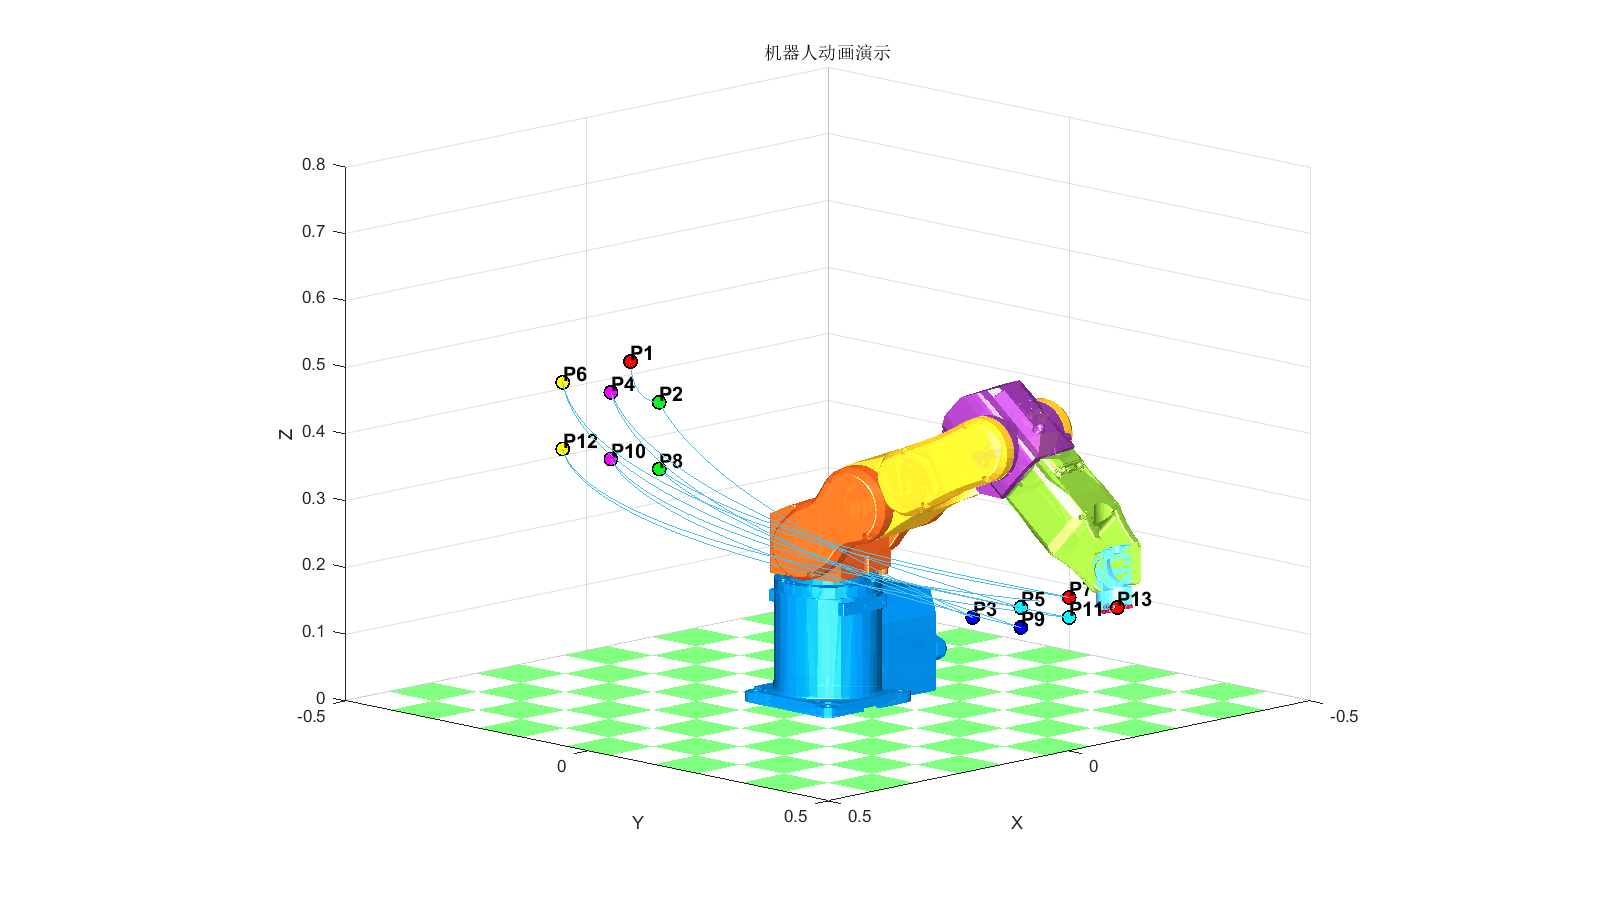

hold off;

## 绘制关节角度、速度、加速度

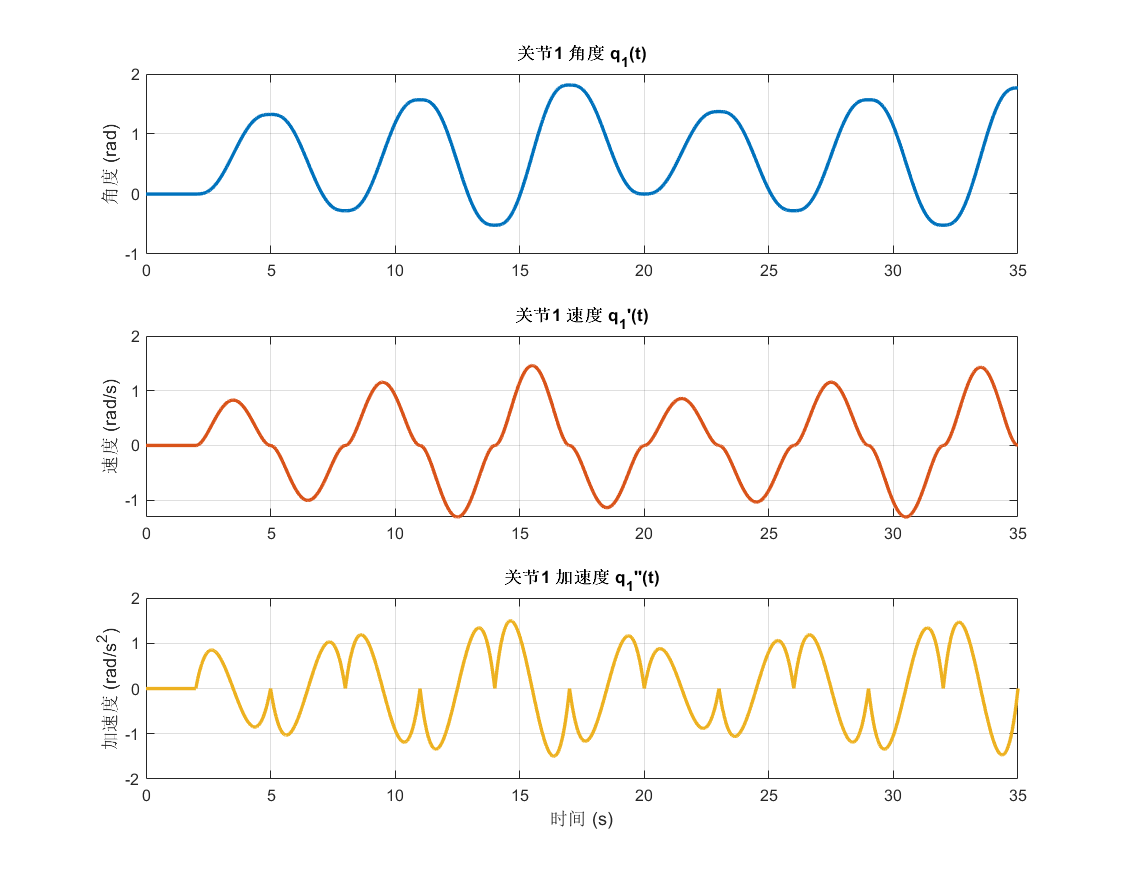

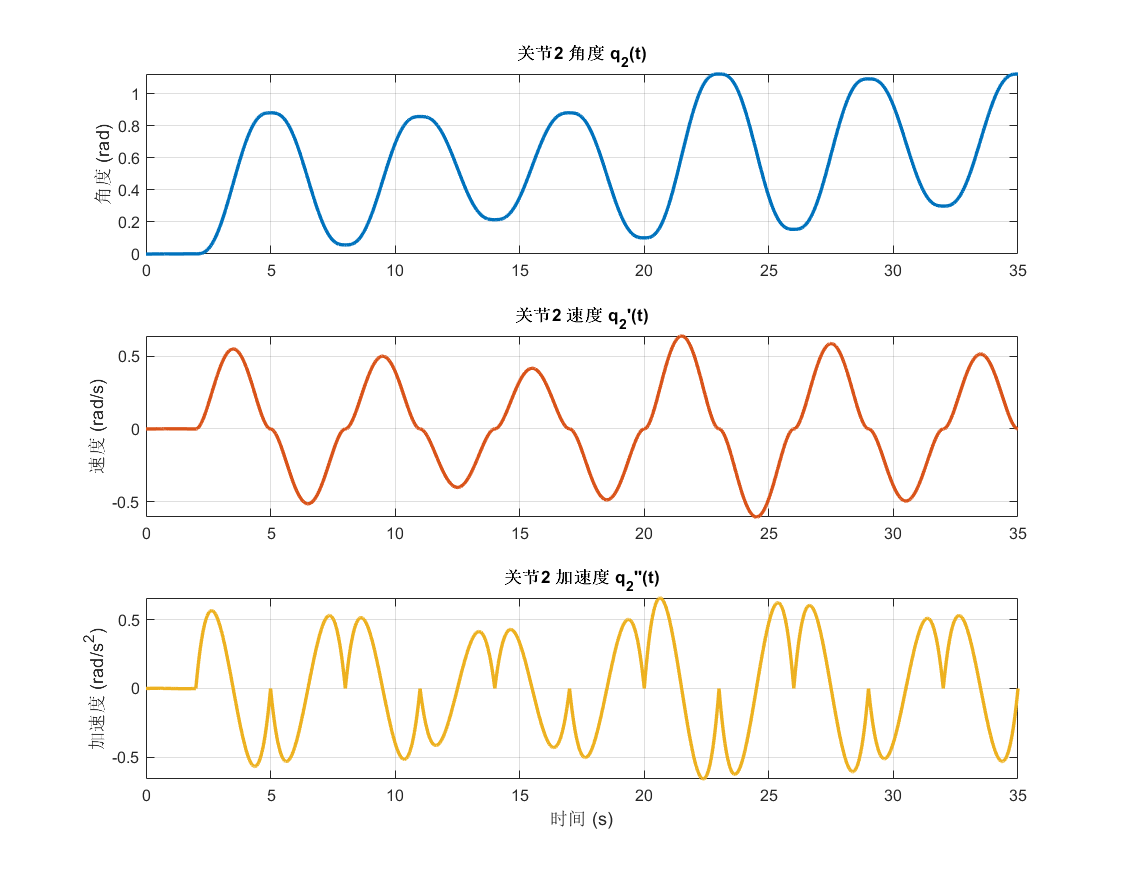

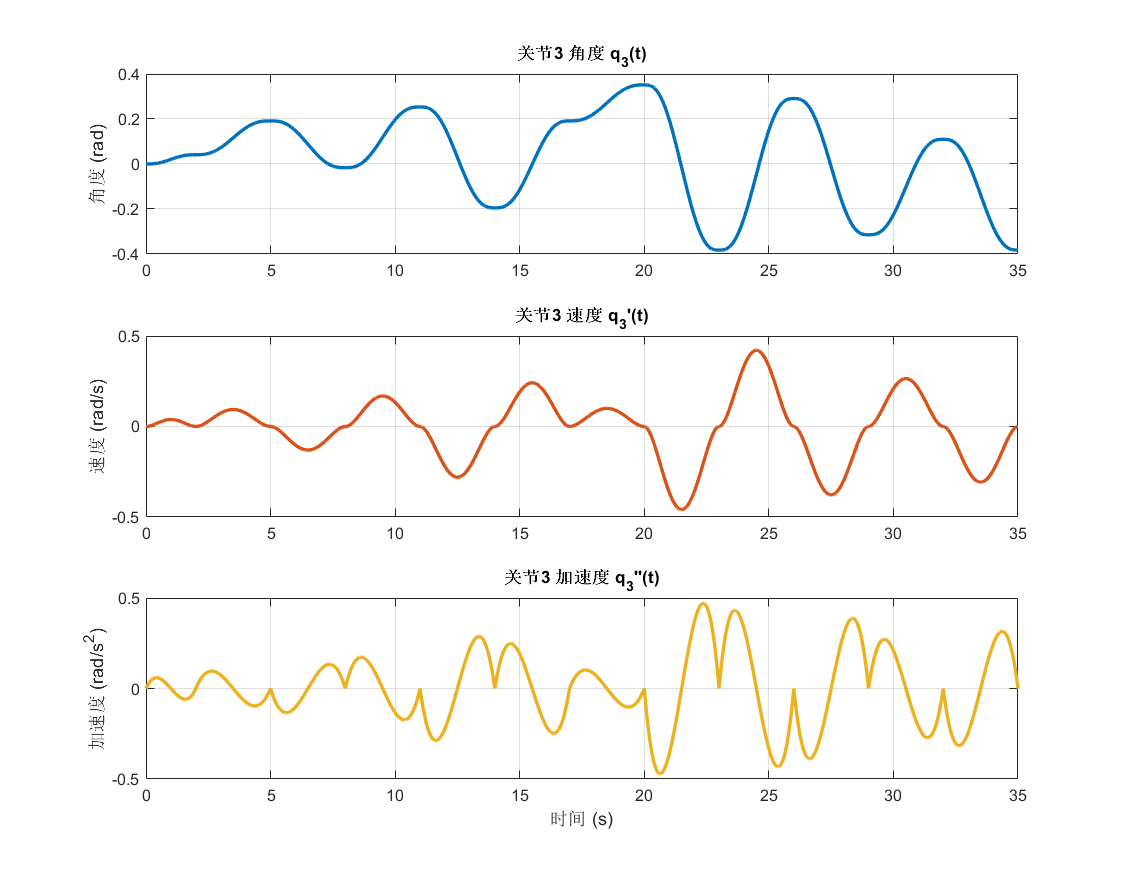

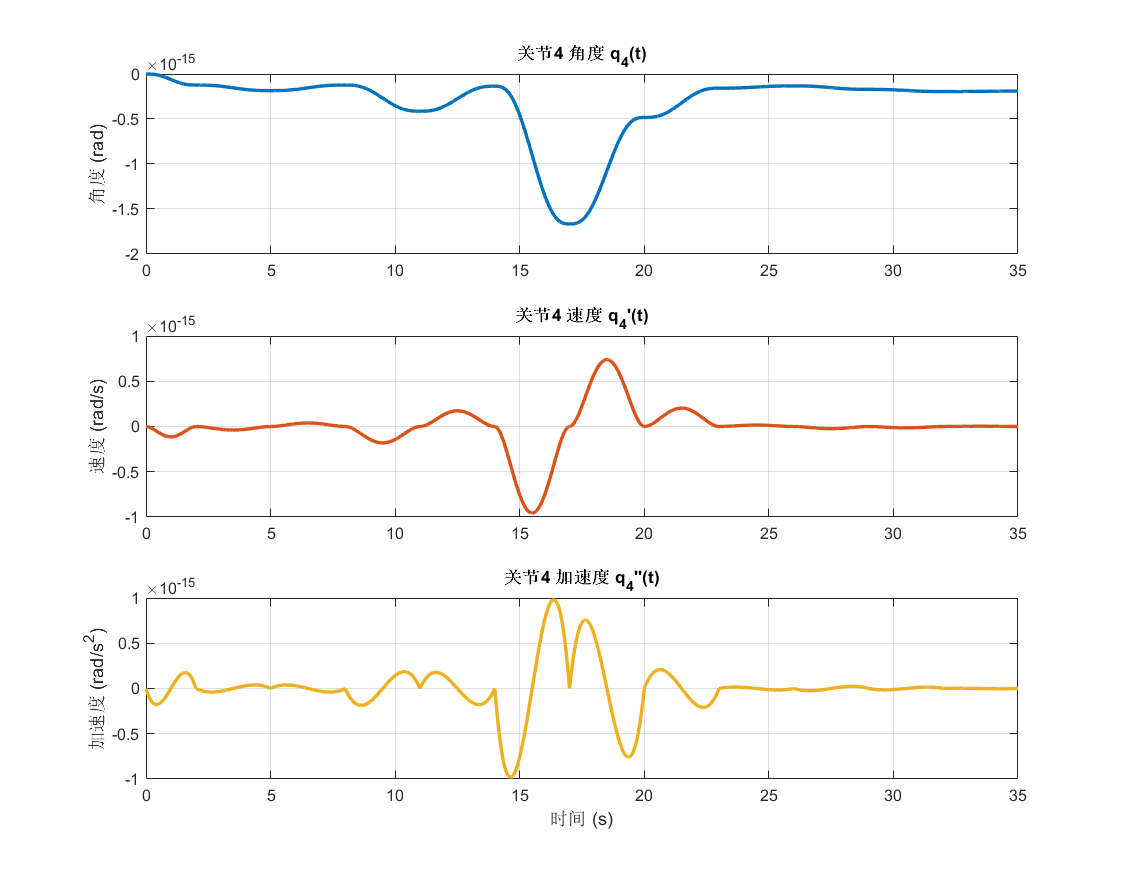

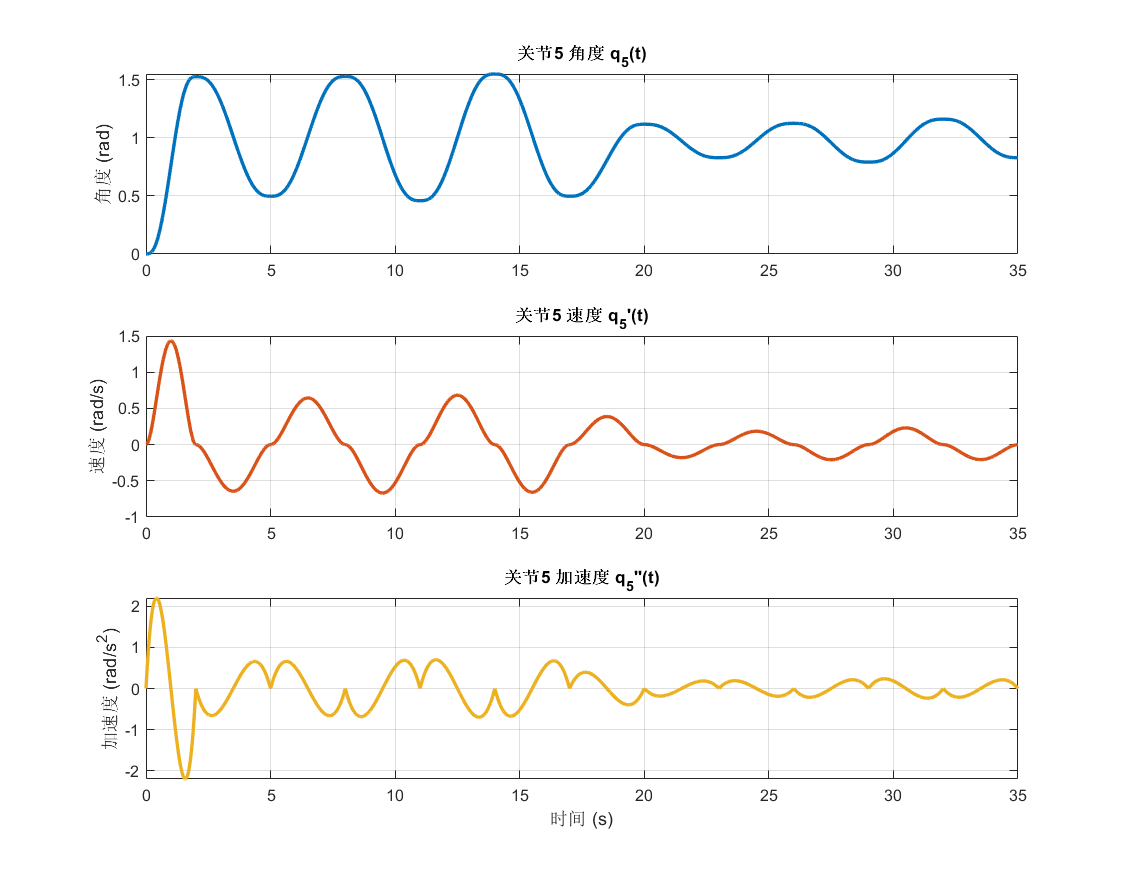

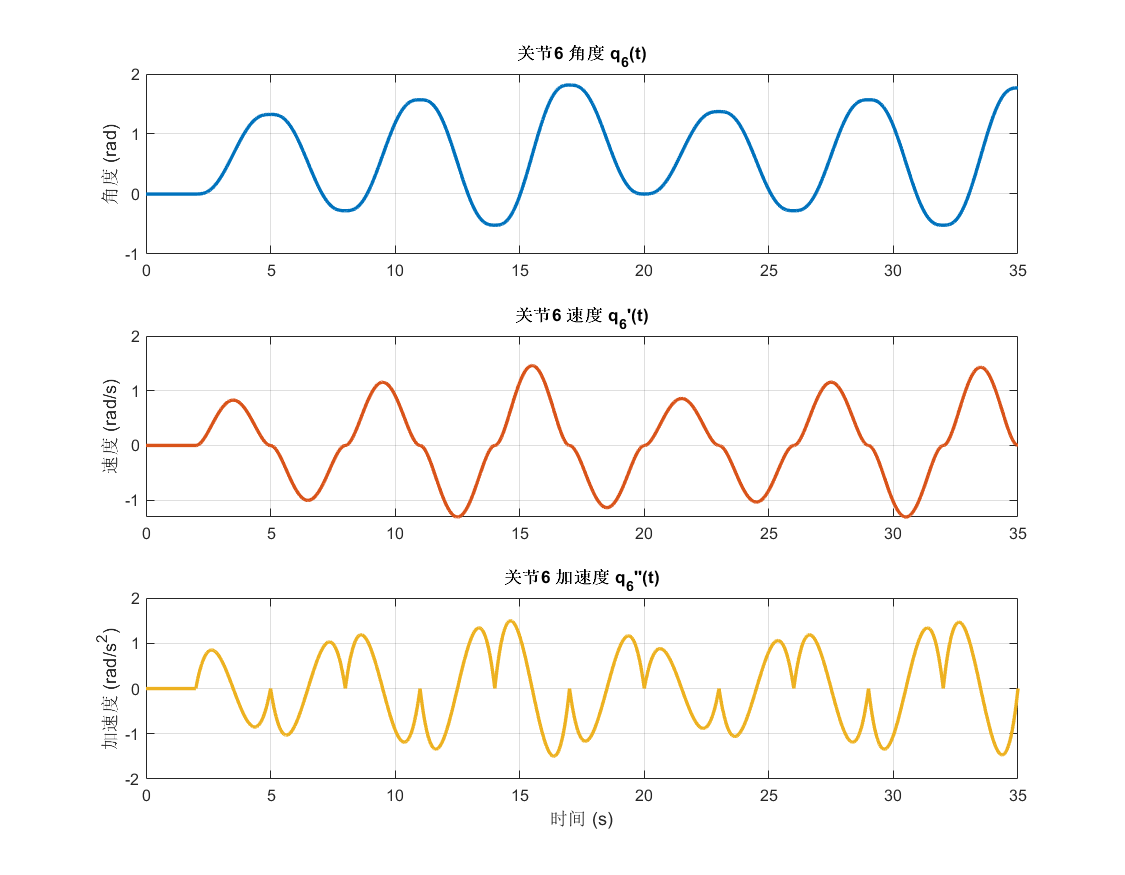

joint_names = {'关节1','关节2','关节3','关节4','关节5','关节6'};

for j = 1:6
    figure('Name', sprintf('%s 运动学曲线', joint_names{j}), 'Position', [50+50*(j-1), 50+30*(j-1), 900, 700]);
    
    % ---------- 1. 关节角度 ----------
    subplot(3,1,1);
    plot(all_time, all_q_traj(:,j), 'LineWidth', 2, 'Color', [0 0.4470 0.7410]);
    grid on;
    ylabel('角度 (rad)', 'FontSize', 11);
    title(sprintf('%s 角度 q_%d(t)', joint_names{j}, j), 'FontSize', 12, 'FontWeight', 'bold');
    
    % ---------- 2. 关节速度 ----------
    subplot(3,1,2);
    plot(all_time, all_qd_traj(:,j), 'LineWidth', 2, 'Color', [0.8500 0.3250 0.0980]);
    grid on;
    ylabel('速度 (rad/s)', 'FontSize', 11);
    title(sprintf('%s 速度 q_%d''(t)', joint_names{j}, j), 'FontSize', 12, 'FontWeight', 'bold');
    
    % ---------- 3. 关节加速度 ----------
    subplot(3,1,3);
    plot(all_time, all_qdd_traj(:,j), 'LineWidth', 2, 'Color', [0.9290 0.6940 0.1250]);
    grid on;
    xlabel('时间 (s)', 'FontSize', 11);
    ylabel('加速度 (rad/s^2)', 'FontSize', 11);
    title(sprintf('%s 加速度 q_%d''''(t)', joint_names{j}, j), 'FontSize', 12, 'FontWeight', 'bold');
end

## 绘制关节力矩

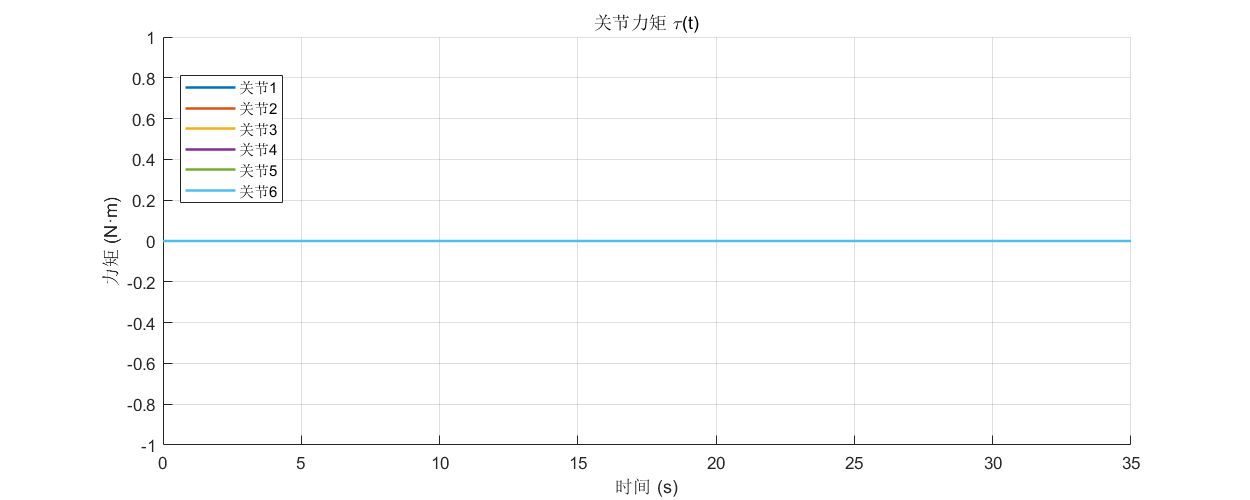

figure('Name','关节力矩','Position',[150 150 1000 400]);
hold on; grid on;
for j = 1:6
    plot(all_time, all_tau(:,j), 'LineWidth', 1.5, 'DisplayName', sprintf('\\tau_%d', j));
end
xlabel('时间 (s)');
ylabel('力矩 (N·m)');
title('关节力矩 \tau(t)');
legend(joint_names, 'Location','best');